s0_add_paths

# Summary:

- Make Gabor filters at different spatial frequencies, finding that filters with more than 3 cycles/deg may have the aliasing problem. (Question: does 3 cycles/deg have the aliasing problem?)

- Compare contrast energy extracted by a single spatial frequency and multiple spatial frequencies. We compared the rescaled contrast energy (divided by the first stimuli) and found consistency between the "multiple" and the "single" cases. However, we found a significant difference in the target stimuli group, suggesting that we should extract energy at more than one spatial frequency. (Question: shall we?)

- We showed that it good to calculate contrast energy on the resized image.

- To avoid the aliasing problem, maybe we can extract energy on the original image and resized the contrast energy image. 

## The filters at different multiple spatial frequencies 

We examined the Gabor filters at different spatial frequencies, finding that 

- when the spatial frequency is more than 3 cycle/deg, the filters shows some aliasing. 

- there is some aliasing at 3 cycle/deg. 

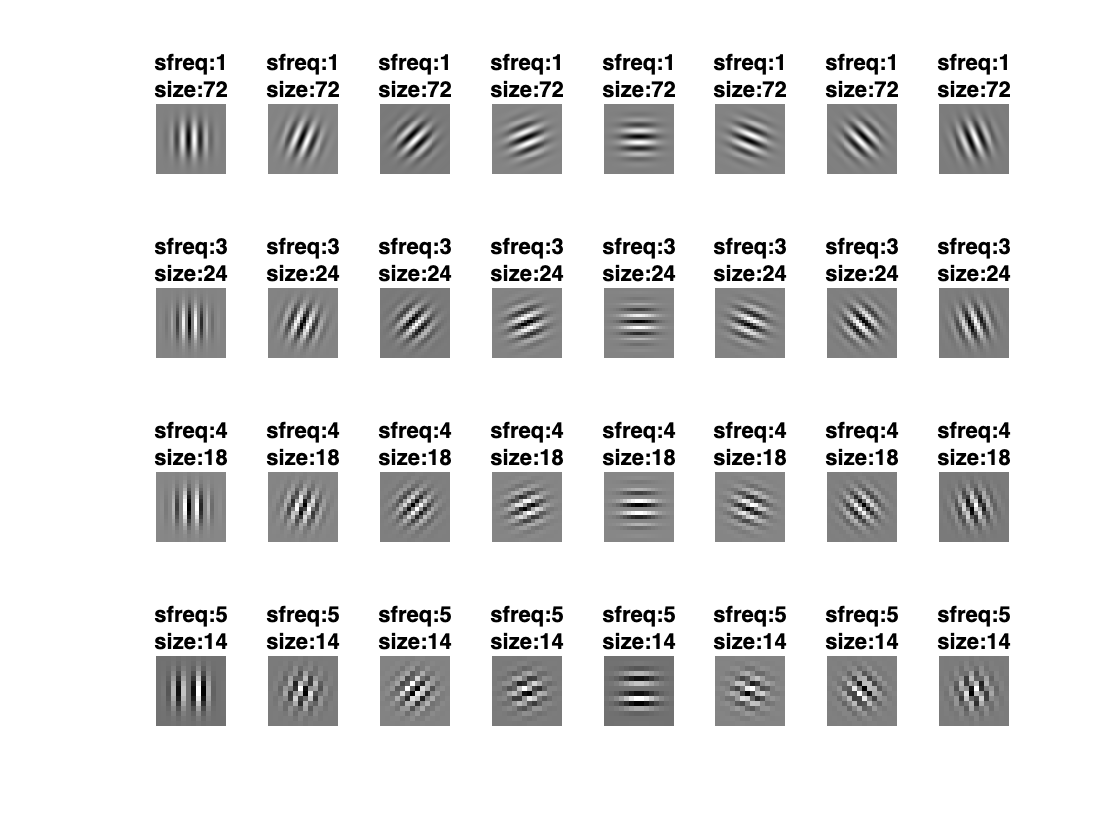

dataset = 1;
fname = sprintf('stimuli-dataset0%1d', dataset);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
stim = double(stimuli);

showFilters(stim, 'multiple', 6);

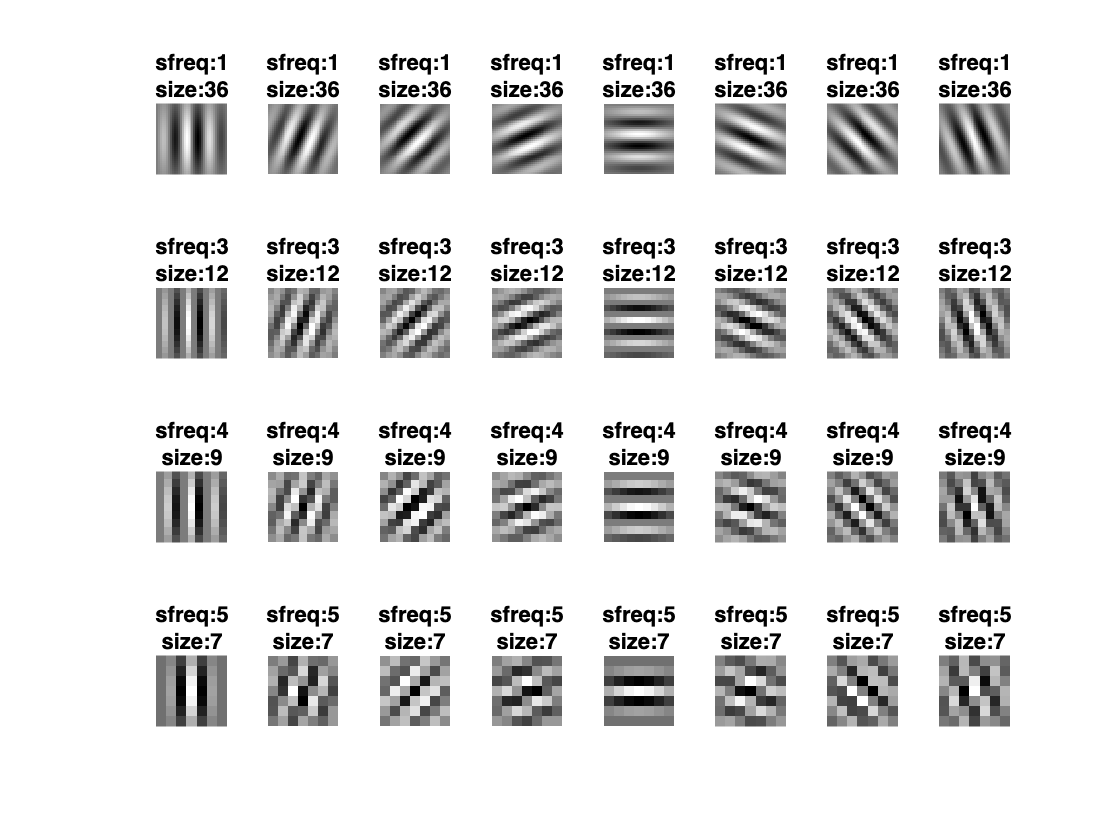

showFilters(stim, 'multiple', 3);

## What shall we do with the multi-frequencies filters? 

We use filters to extract the contrast energy at frequencies other than three cycles/deg. The contrast energy over different spatial frequencies will be combined before modeling. This is to check whether it is enough for us only to consider the energy at three cycles/deg. 

## 
$$E(x,y,\theta) = \sum_{\phi, f}\left(\sum_{x',y'}F(x',y',\theta,f, \phi) I(x-x',y-y')\right)^2$$


## Is three cycles/deg enough？

The idea is to compare the ratios of all contrast energy to the first stimuli in the dataset. The concerns are eliminated if the single-frequency filters expose similar ratios to those at multiple frequencies. 

Consider filters with spatial frequencies at 1, 2, 3, 4 cycles/deg.

..........

..........


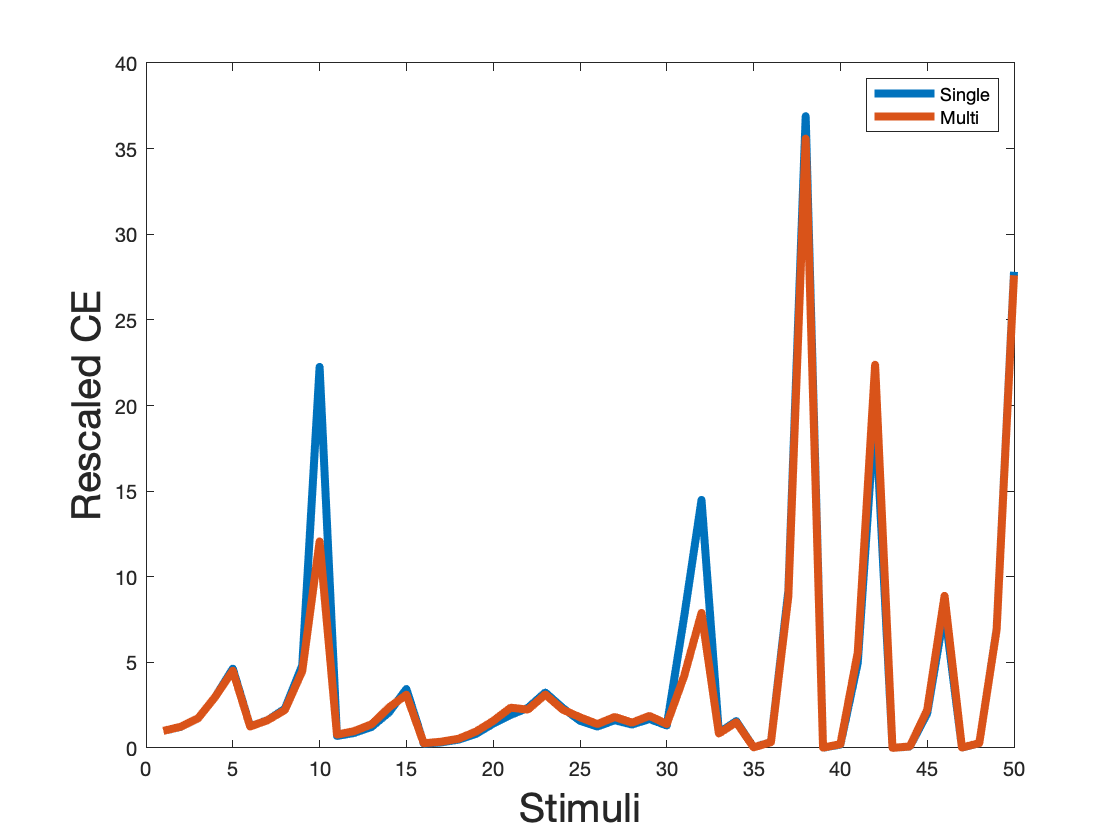

ds = 1;
CEatMultiSF(ds);

..........

..........


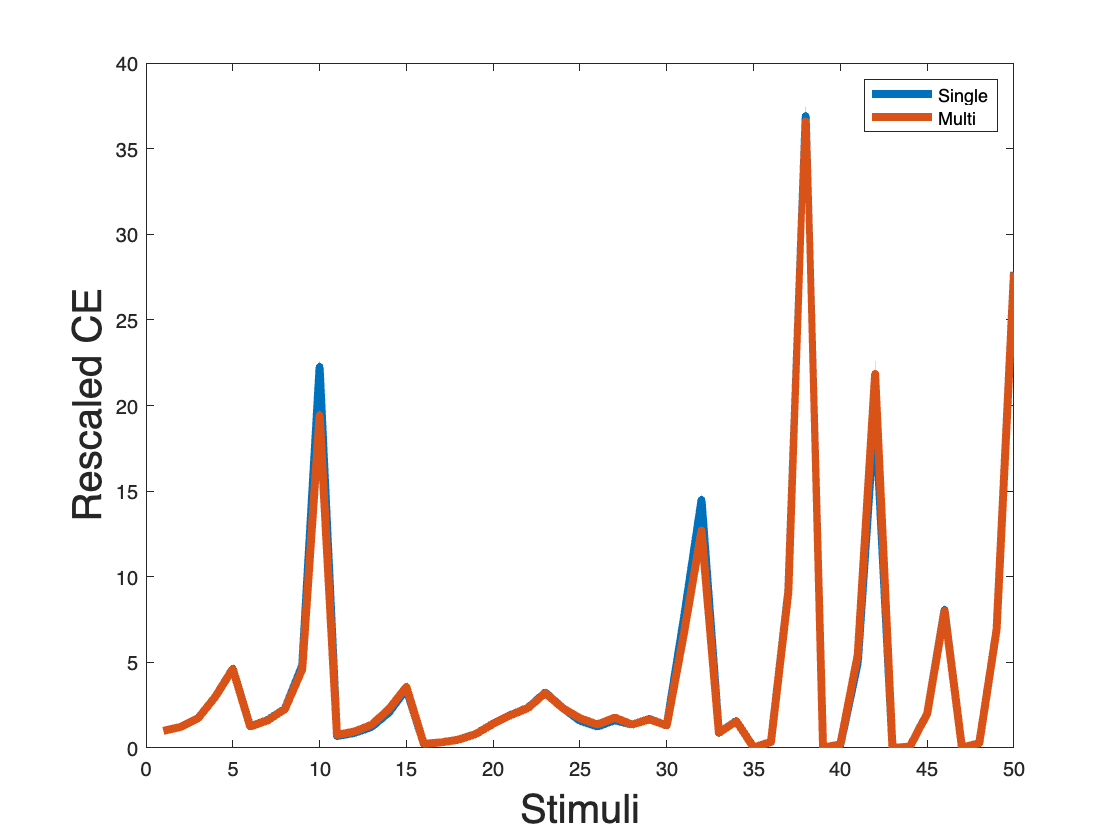

%% Compare 3cyc/deg and 3, 4 cyc/deg
ds = 1;
CEatMultiSF(ds, 'resize', [3, 4]);

..........

..........


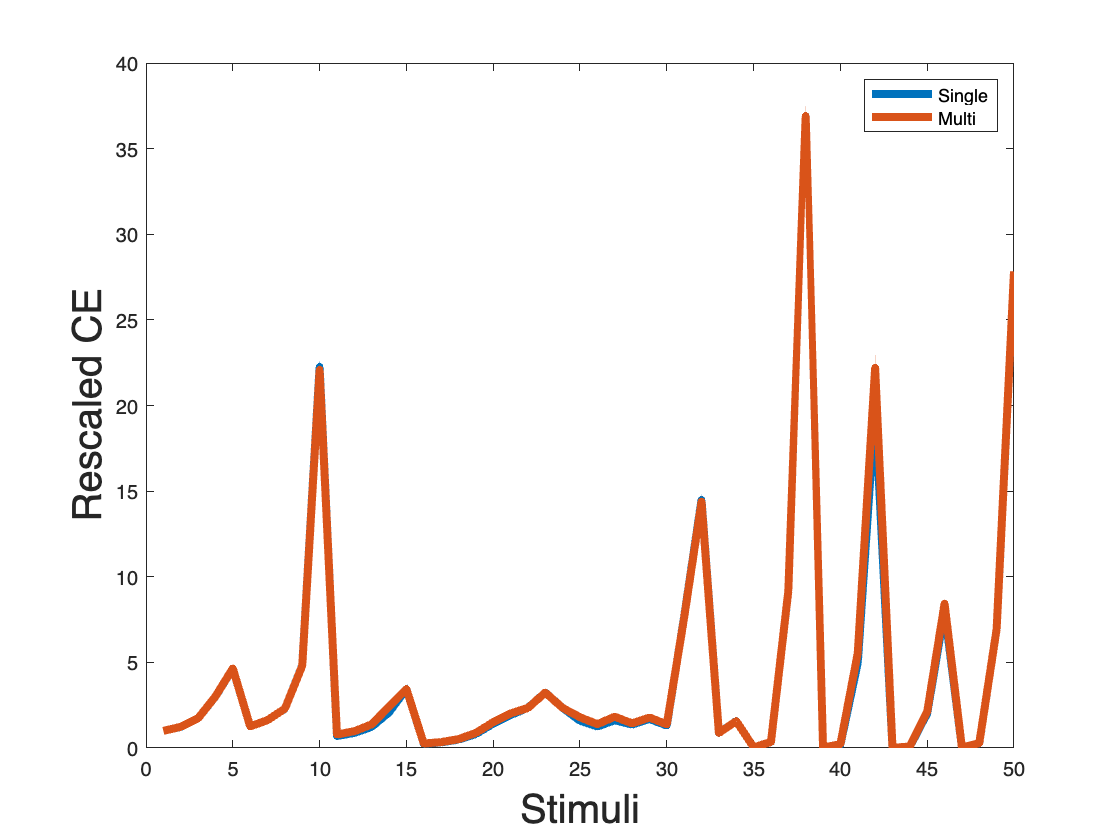

%% Compare 3cyc/deg and 1, 3 cyc/deg
ds = 1;
CEatMultiSF(ds, 'resize', [1, 3]);

#### What are these image? 

DS 1 stim 9, 10; 31, 32, 33, 34 

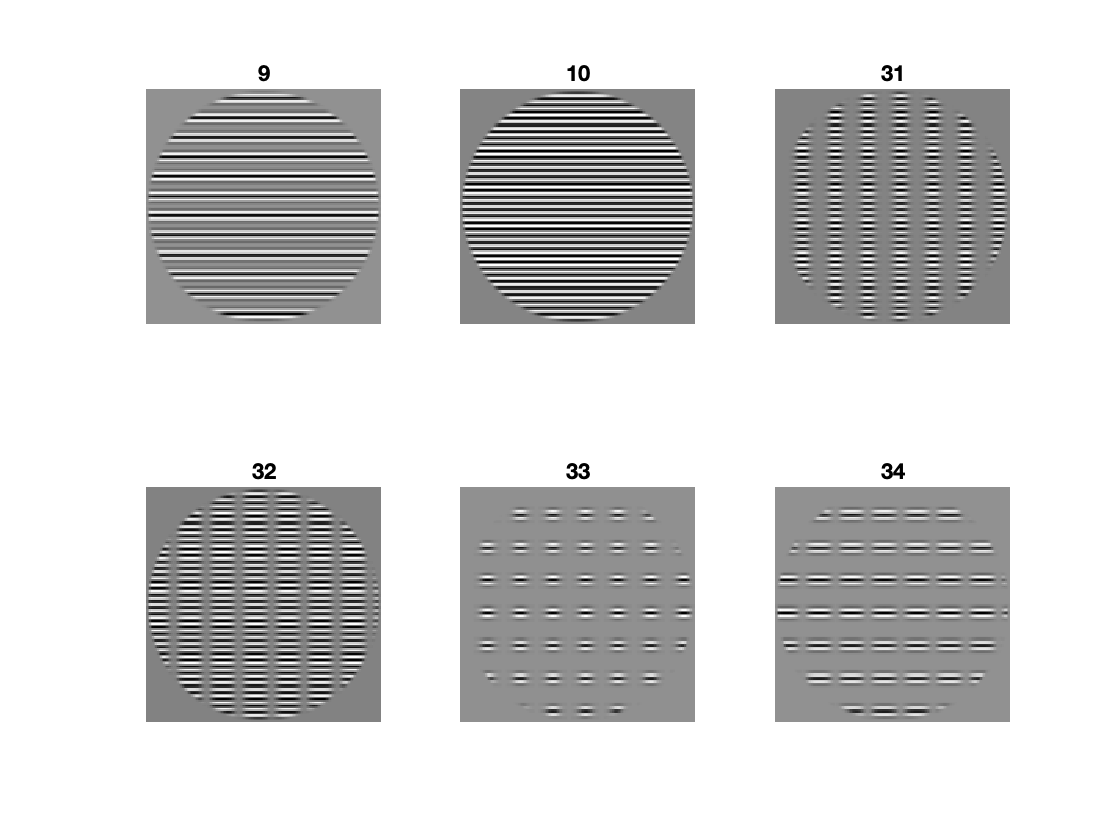

ds = 1; 
labels = [9, 10, 31, 32, 33, 34];

fname = sprintf('stimuli-dataset%02d.mat', ds);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')

figure();
for i=1:length(labels)
    subplot(2, 3, i)
    imshow(stimuli(:, :, 5, labels(i)), [])
    title(labels(i))
end

In DS1, the 10th stimulus has lower contrast energy when convolving with filters at multiple spatial frequencies. This is because the contrast energy of this stimulus is mostly captured by filter @ 3 cycles/deg, while other stimuli are not. 

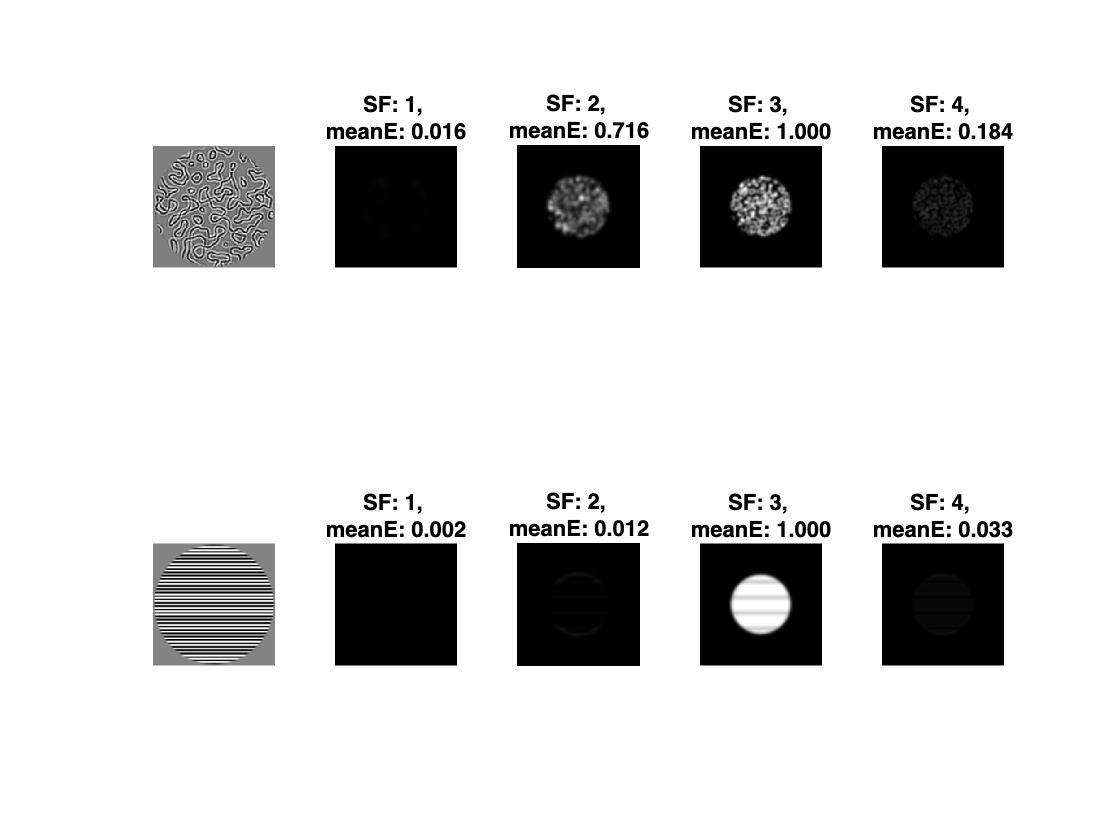

ds=1;
fname = sprintf('stimuli-dataset%02d.mat', ds);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')
labels = [5, 10]; 
figure();
for j = 1:2
    stim = stimuli(:, :, 5, labels(j));
    subplot(2, 5, (j-1)*5+1)
    imshow(stim, [])
    E = convimg(stim, 'multiple');
    E_freq = squeeze(mean(E, 3));
    emax = max(E_freq(:));
    emin = min(E_freq(:));
    ppc = [1, 2, 3, 4];
    Emeans = sum(E_freq, [1,2]);
    Emeans = Emeans ./ Emeans(3);
    for i=1:4
        subplot(2, 5, (j-1)*5+i+1)
        imshow(E_freq(:, :, i), [emin, emax])
        title(sprintf('SF: %d, \nmeanE: %.3f', ppc(i), Emeans(i)))
    end
end

..........

..........


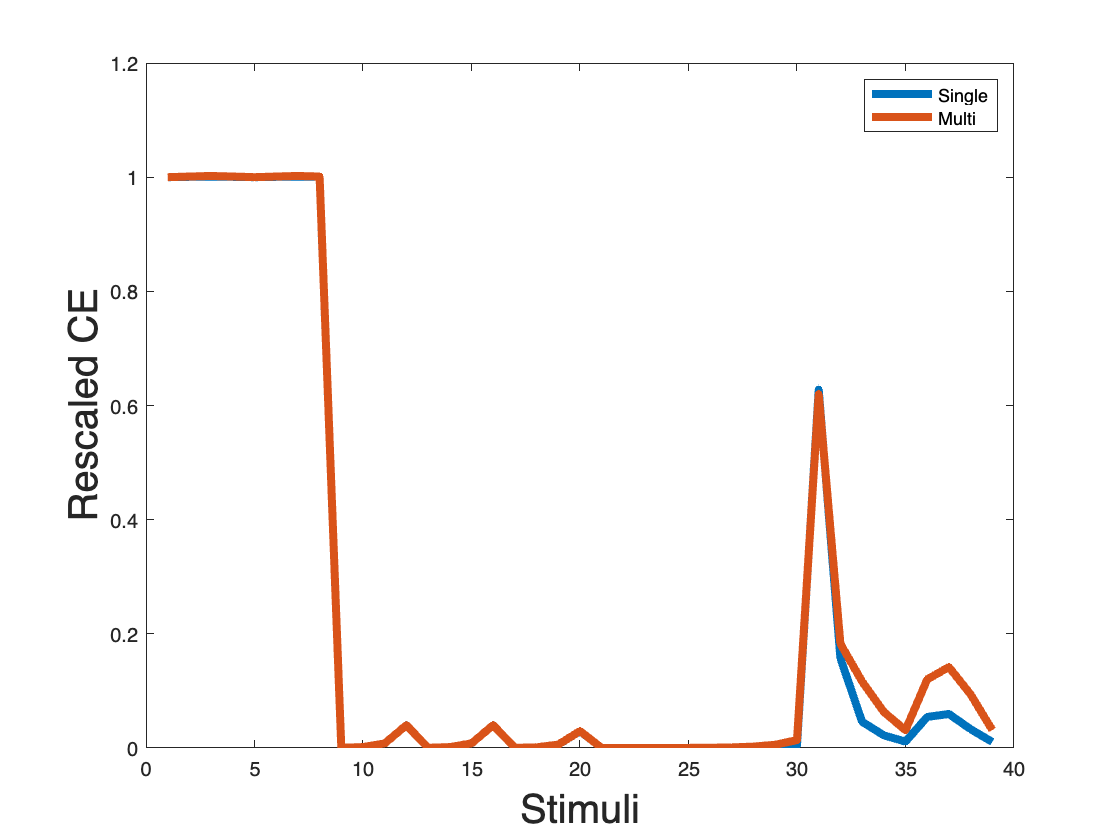

%% Compare 3cyc/deg and 1,2,3,4 cyc/deg
ds = 4;
CEatMultiSF(ds);

..........

..........


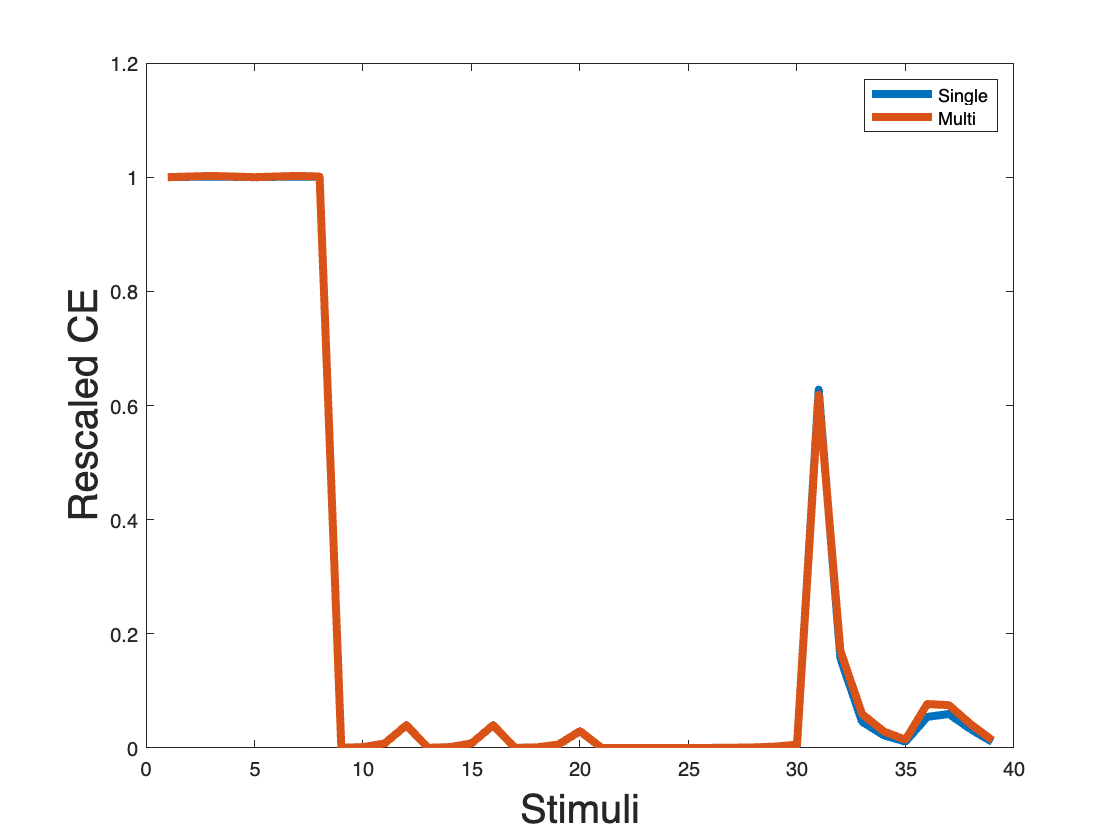

%% Compare 3cyc/deg and 3,4 cyc/deg
ds = 4;
CEatMultiSF(ds, 'resize', [3, 4]);

..........

..........


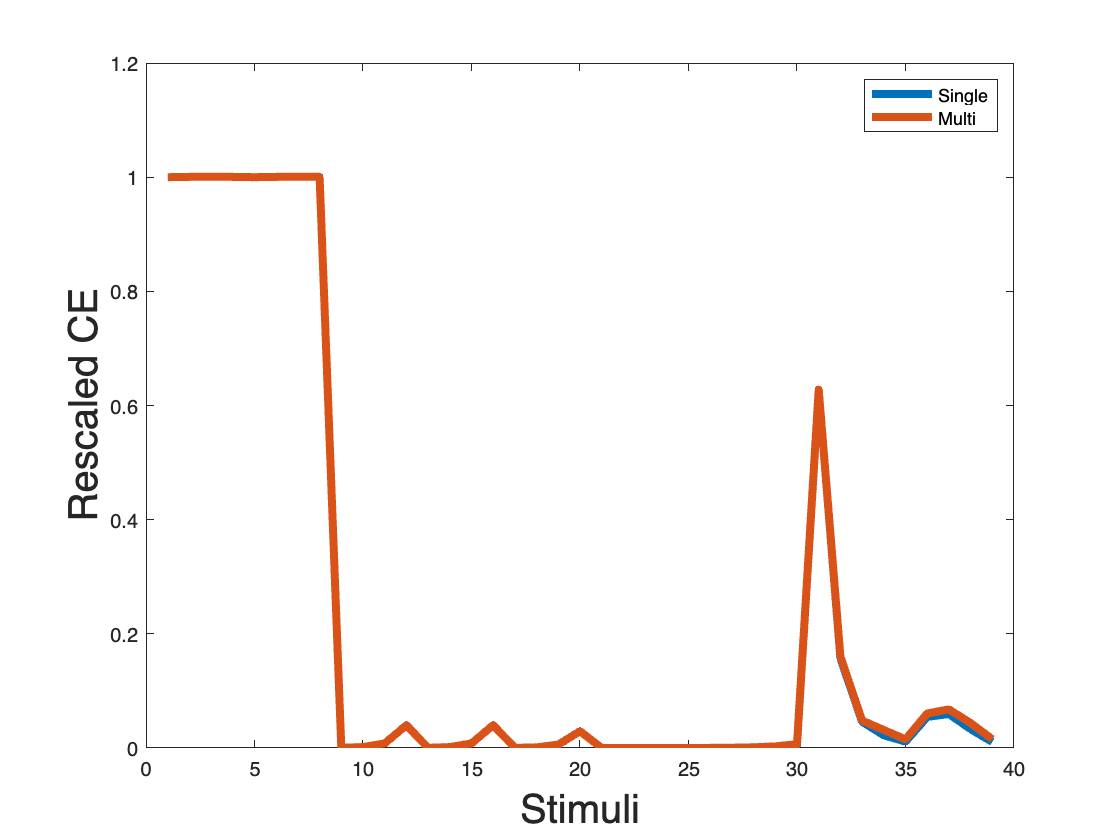

%% Compare 3cyc/deg and 1, 3 cyc/deg
ds = 4;
CEatMultiSF(ds, 'resize', [1, 3]);

#### What are these image? 

DS 4 stim 31-40

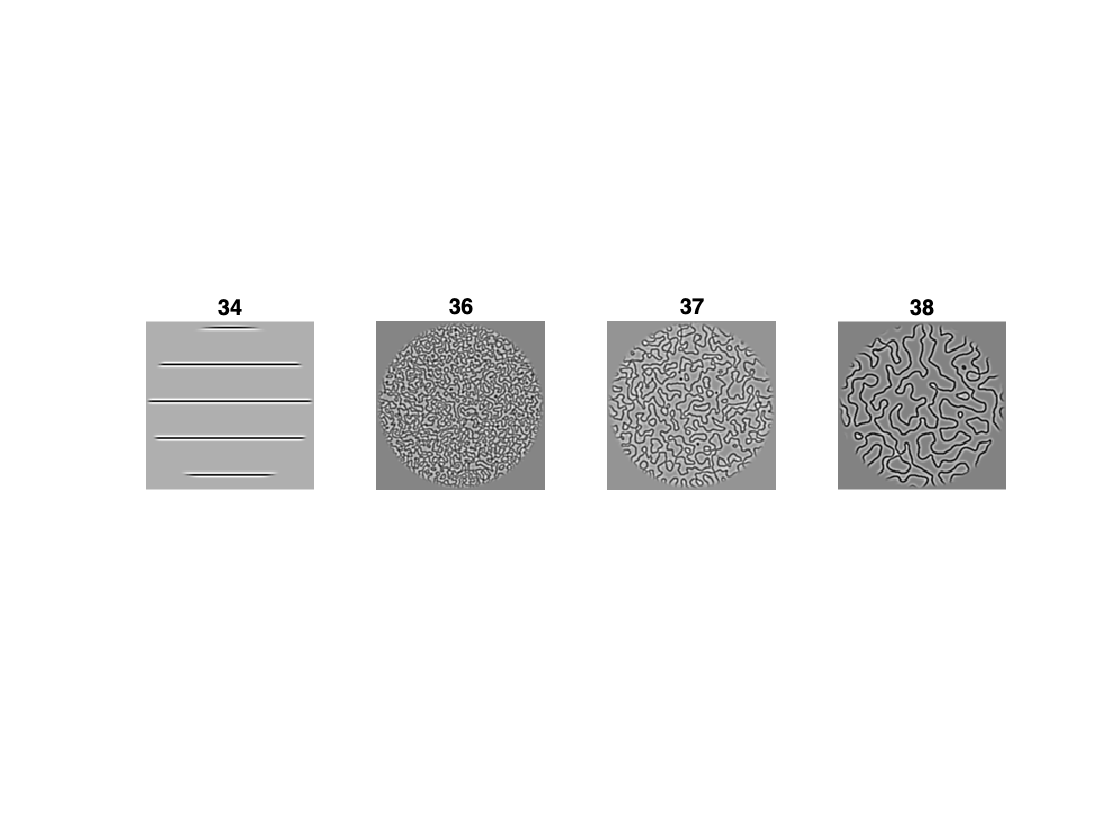

ds = 4; 
labels = [34, 36, 37, 38];

fname = sprintf('stimuli-dataset%02d.mat', ds);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')

figure();
for i=1:length(labels)
    subplot(1, 4, i)
    imshow(stimuli(:, :, 5, labels(i)), [])
    title(labels(i))
end

In DS4, the 34th, 37th stimuli have highe contrast energy when convolving with filters at multiple spatial frequencies. This is because these stimuli have contrast energy @ 1 cycle/deg, which is not captured by the filter @ a single spatial frequency.

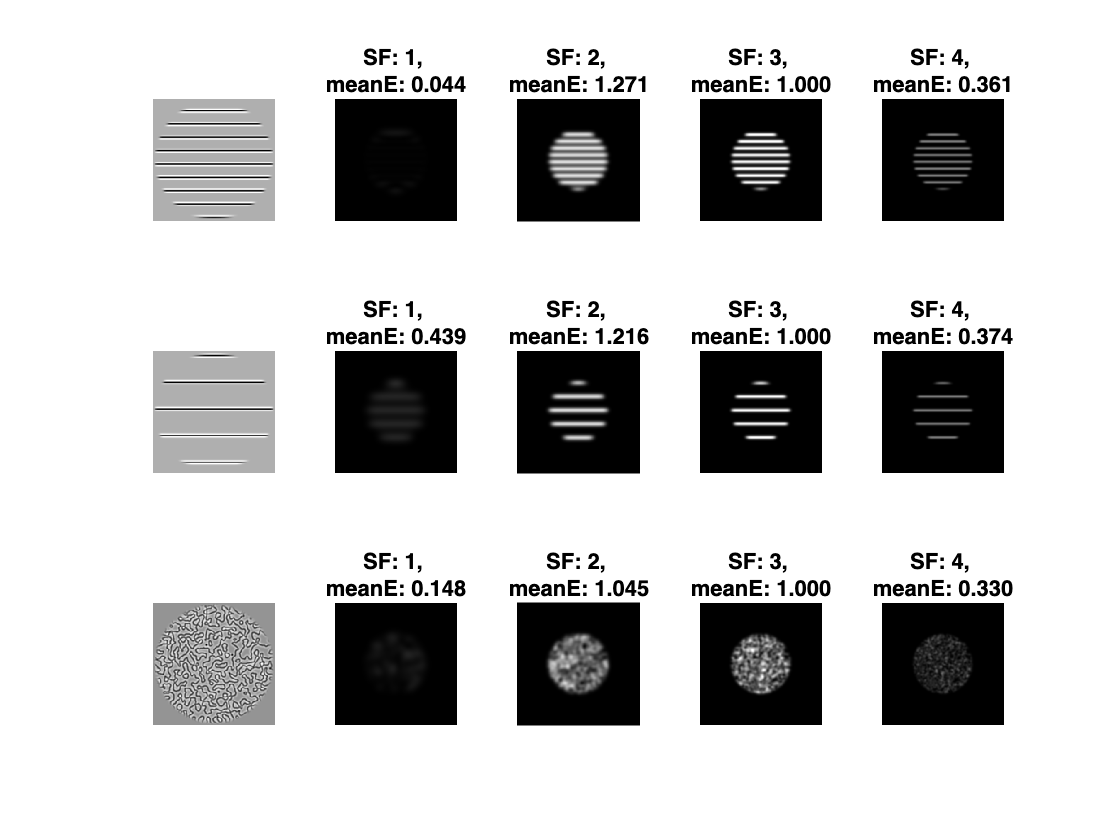

ds=4;
fname = sprintf('stimuli-dataset%02d.mat', ds);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')
labels = [33, 34, 37]; 
figure();
for j = 1:3
    stim = stimuli(:, :, 5, labels(j));
    subplot(3, 5, (j-1)*5+1)
    imshow(stim, [])
    E = convimg(stim, 'multiple');
    E_freq = squeeze(mean(E, 3));
    emax = max(E_freq(:));
    emin = min(E_freq(:));
    ppc = [1, 2, 3, 4];
    Emeans = sum(E_freq, [1,2]);
    Emeans = Emeans ./ Emeans(3);
    for i=1:4
        subplot(3, 5, (j-1)*5+i+1)
        imshow(E_freq(:, :, i), [emin, emax])
        E_mean = sum(E_freq(:, :, i), [1, 2]);
        title(sprintf('SF: %d, \nmeanE: %.3f', ppc(i), Emeans(i)))
    end
end

## Does reszing image matters?

The concern we want to address here is whether it is appropriate to resize the image.

Still, we compare the ratios to answer the questions. 

..........

..........


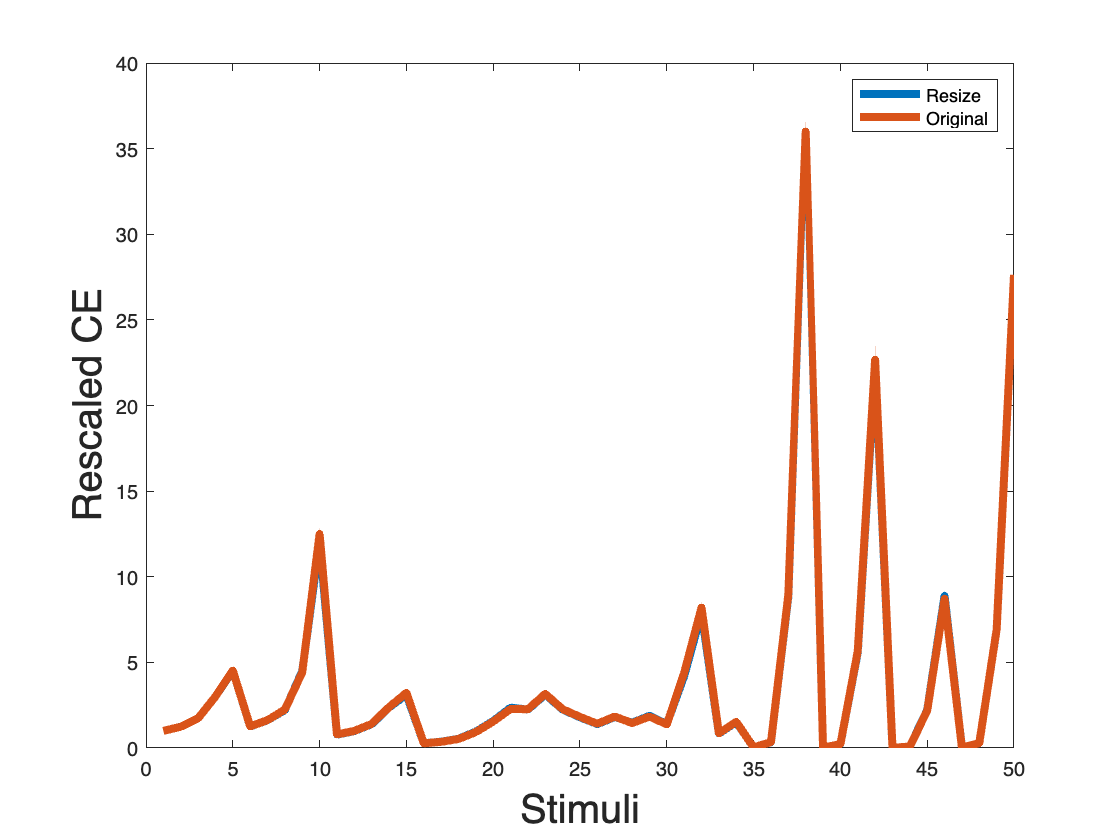

ds = 1;
orig_resize(ds);

ds = 4;
orig_resize(ds);

## Appendix: the functions used in this script

function showFilters(stim, sf, support, filter_cpd)
if (nargin < 4), filter_cpd = [1, 2, 3, 4]; end
if (nargin < 3), support = 3; end % cycle per filter
if (nargin < 2), sf = 'single'; end

% the frequency vectors
switch sf
    % the images were band-passed at 3 cycles per degree
    case 'single', filter_cpd = 3;
end

% the orientation vectors
radians     = linspace(0, pi, 9);
orients     = radians(1:end-1);

% other parameters
numpix     = size(stim, 1);
pixperdeg  = numpix / 12.5;

ppc        = pixperdeg ./ filter_cpd;

% create filters
[Gabor_c, Gabor_s]=makeGaborFilter(ppc, orients, support);

% visualize
nR = size(Gabor_c, 2); nC = size(Gabor_c, 1);
for k= 1:1
    for j = 1:nR
        for i = 1:nC
            subplot(nR, nC, (j-1)*nC+i)
            sf = filter_cpd(j);
            switch k
                case 1
                    imshow(Gabor_c{i, j}, []);
                    img_size = size(Gabor_c{i, j},1);
                case 2
                    imshow(Gabor_s{i, j}, []);
                    img_size = size(Gabor_s{i, j},1);
            end
            title(sprintf('sfreq:%01g\nsize:%d', sf, img_size))
        end
    end
end

end

function CEatMultiSF(which_data, src, filter_cpd)
if (nargin < 3); filter_cpd = [1, 2, 3, 4]; end
if (nargin < 2); src = 'resize'; end
switch src
    case 'resize'; fname = sprintf('stimuli-dataset%02d.mat', which_data);
    case 'origin'; fname = sprintf('stimuli-dataset%02d_orig.mat', which_data);
end

path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')
labelVec = 1:size(stimuli, 4);
E_ori = cal_E(stimuli, labelVec, 'orientation', which_data, 3);
E_single = mean(E_ori, [1, 2]);
E_ori = cal_E(stimuli, labelVec, 'orientation', which_data, filter_cpd);
E_multi = mean(E_ori, [1, 2]);
E_single = squeeze(E_single);
E_multi  = squeeze(E_multi);
scaled_E_sing = E_single ./ E_single(1);
scaled_E_mult = E_multi  ./ E_multi(1);
figure();
plot(labelVec, scaled_E_sing, 'LineWidth', 4);
hold on
plot(labelVec, scaled_E_mult, 'LineWidth', 4);
hold off
legend('Single', 'Multi')
xlabel('Stimuli', FontSize=20)
ylabel('Rescaled CE', FontSize=20)

end

function orig_resize(which_data)

fname = sprintf('stimuli-dataset%02d.mat', which_data);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')
stimuli = double(stimuli);
labelVec = 1:size(stimuli, 4);
E_ori = cal_E(stimuli, labelVec, 'orientation', which_data, 'multiple');
E_resize = mean(E_ori, [1, 2]);

fname = sprintf('stimuli-dataset%02d_orig.mat', which_data);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli')
stimuli = double(stimuli);
stimuli = stimuli ./ 255 - .5;
labelVec = 1:size(stimuli, 4);
E_ori = cal_E(stimuli, labelVec, 'orientation', which_data, 'multiple');
E_orig = mean(E_ori, [1, 2]);

E_resize = squeeze(E_resize);
E_orig  = squeeze(E_orig);
scaled_E_resize = E_resize ./ E_resize(1);
scaled_E_orig   = E_orig   ./ E_orig(1);
figure();
plot(labelVec, scaled_E_resize, 'LineWidth', 4);
hold on
plot(labelVec, scaled_E_orig, 'LineWidth', 4);
hold off
legend('Resize', 'Original')
xlabel('Stimuli', FontSize=20)
ylabel('Rescaled CE', FontSize=20)

end

function conEnergy=convimg(stimulus, sf)
if (nargin < 2), sf = 'single'; end

% the frequency vectors
switch sf
    % the images were band-passed at 3 cycles per degree
    case 'single', filter_cpd = 3;
    case 'multiple', filter_cpd = [1, 2, 3, 4];
end

% the orientation vectors

% other parameters
fovs        = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
fov         = fovs(1);
numpix      = size(stimulus,1);
pixperdeg   = numpix / fov;
ppc         = pixperdeg ./ filter_cpd; % pixels per cycle
support     = 6; % cycles per filter
radians     = linspace(0, pi, 9);
thetavec    = radians(1:end-1);
padsize     = max(ppc) .* support;

% create filters
[G_c, G_s]=makeGaborFilter(ppc, thetavec, support);

% get the stimulus and pad the stimulus
padstimulus = zeros(numpix+padsize*2, numpix+padsize*2);
padstimulus(padsize+(1:numpix), padsize+(1:numpix)) = stimulus;
stimulus = padstimulus;

sz = size(stimulus, 1);
conEnergy = nan(sz, sz, length(thetavec), length(ppc));

for i = 1:length(ppc)
    % for all orientaitons 
    for j = 1:length(thetavec)
        
        % get the Gabor filters
        Gabor_c = G_c{j, i};
        Gabor_s = G_s{j, i};
        
        % compute the energy 
         CE = conv2(stimulus,Gabor_c,'same').^2 ...
            + conv2(stimulus,Gabor_s,'same').^2;
         conEnergy(:, :, j, i) = CE; 
    end
end


end 